clear all
clc 
close all

[A,B,C,D]=linmod('exam2021_simulink');
P=ss(A,B,C,D);
G = tf(P)

G =
 
  -10 s^2 - 15 s - 10
  -------------------
          s^3
 
Continuous-time transfer function.



damp(G)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
  0.00e+00    -1.00e+00       0.00e+00           Inf       
  0.00e+00    -1.00e+00       0.00e+00           Inf       
  0.00e+00    -1.00e+00       0.00e+00           Inf       


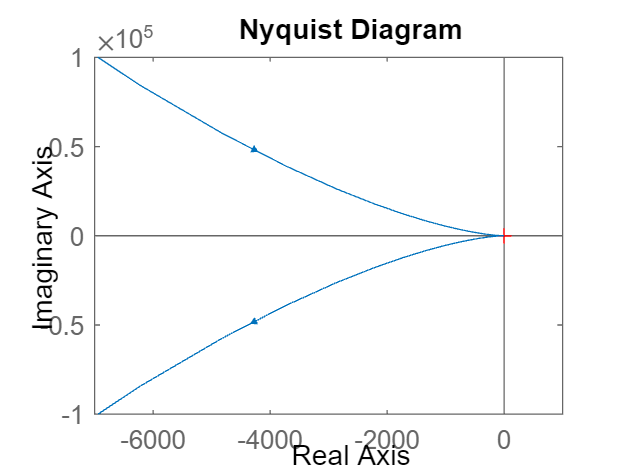

nyquist(-G)

G_resp = evalfr(-G,1*i)

## Antiwind-up Design

clear all
clc 
close all

[A,B,C,D]=linmod('exam2021_anti_simulink');
P=ss(A,B,C,D);
G = tf(P)

G =
 
  -25 s^2 - 25 s - 10
  -------------------
     s^4 + 11 s^3
 
Continuous-time transfer function.



damp(G)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
  0.00e+00    -1.00e+00       0.00e+00              Inf    
  0.00e+00    -1.00e+00       0.00e+00              Inf    
  0.00e+00    -1.00e+00       0.00e+00              Inf    
 -1.10e+01     1.00e+00       1.10e+01         9.09e-02    


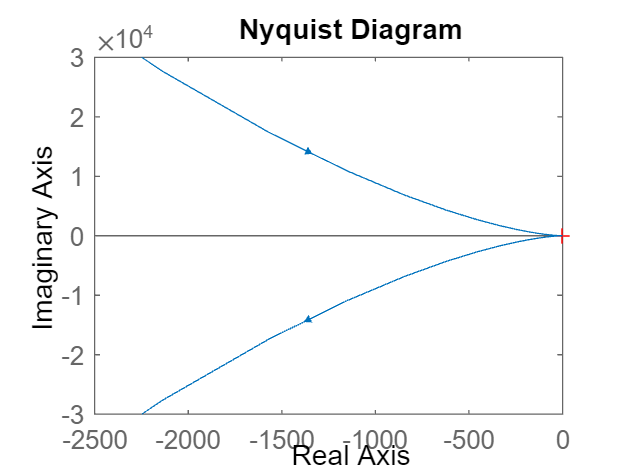

nyquist(-G)

G_resp = evalfr(-G,0.663*i)

G_resp = -5.1702 + 0.0030i



% phase plane analysis technique permits to
% compute exact characterizations of stability domains

% Describing functions are not accurate and depend
% on frequency of G(s)

% SIDF depends on both x0 and w
% SIDF with a static non-linearity only depends on x0

% x0 = 4*M/(pi*N) %Amplitude